
function vopt = solve_t_positive(c1, c2, c3, m_1, m_2, m_3, opts)
% SOLVE_T_POSITIVE Solve the 3-equation system with t >= 0.
% vopt = solve_t_positive(c1,c2,c3,x0,lb,ub,opts)
%
% Inputs (optional after c's):
%  x0   - initial guess (3x1 or 1x3).
%  lb   - lower bounds (3x1).
%  ub   - upper bounds (3x1).
%  opts - options structure for lsqnonlin/fmincon. If empty, sensible defaults used.
%
% Output:
%  vopt - 1x3 row vector [x y t].
%
% Uses lsqnonlin if available, otherwise falls back to fmincon minimizing sum(res.^2).
    

    % User defined:
    x0 = [0;0;1e-3];   %Refine the initial estimate (reduces the required number of iterations)


    lb  = [-inf; -inf; 0];   %Solution bounds (boundaries of the drone's position)
    ub  = [ inf;  inf; Inf]; 

    x0 = x0(:); lb = lb(:); ub = ub(:);

    tol = 1e-6;  %Solution tolerence


    % anonymous residuals (backbone)
    res = @(v) [
        (v(1)-m_1(1))^2 + (v(2)-m_1(2))^2 - (v(3)+c1)^2 * 300^2;
        (v(1)-m_2(1))^2 + (v(2)-m_2(2))^2 - (v(3)+c2)^2 * 300^2;
        (v(1)-m_3(1))^2 + (v(2)-m_3(2))^2 - (v(3)+c3)^2 * 300^2
    ];

    % Default options
    if nargin < 7 || isempty(opts)
        if exist('lsqnonlin','file')
            opts = optimoptions('lsqnonlin','Display','off','TolFun',1e-12);
        else
            opts = optimoptions('fmincon','Display','off','OptimalityTolerance',1e-12);
        end
    end

    % Try lsqnonlin
    if exist('lsqnonlin','file')
        try
            v = lsqnonlin(res, x0, lb, ub, opts);
        catch
            v = fallback_fmincon(res, x0, lb, ub, opts);
        end
    else
        v = fallback_fmincon(res, x0, lb, ub, opts);
    end

    r = res(v);        % 3x1
    if all(abs(r) <= tol)
        vopt = reshape(v,1,[]);
    else
        vopt = [];     % returns empty if the solution isnt close enough to the real awnser
    end
end

function v = fallback_fmincon(res, x0, lb, ub, opts)
    % minimize sum(res.^2) with fmincon
    fun = @(z) sum((res(z)).^2);
    % ensure options suitable for fmincon
    if ~isfield(opts, 'Solver') && ~isa(opts, 'optim.options.Fmincon')
        fopts = optimoptions('fmincon','Display','off','OptimalityTolerance',1e-12);
    else
        fopts = opts;
    end
    v = fmincon(fun, x0, [], [], [], [], lb, ub, [], fopts);
end



function h = plotCircle(center, R, N)
% PLOTCIRCLE Plot a circle given its center and radius.
%   h = plotCircle(center, R) plots a circle centered at center = [cx cy]
%   with radius R using 100 points, returns plot handle h.
%
%   h = plotCircle(center, R, N) uses N points around the circle.
%
% Example:
%   plotCircle([1,2], 0.5, 200);
%
    arguments
        center (1,2) double
        R (1,1) double {mustBeNonnegative(R)}
        N (1,1) double {mustBePositive, mustBeInteger} = 100
    end

    cx = center(1);
    cy = center(2);

    theta = linspace(0, 2*pi, N);
    x = cx + R * cos(theta);
    y = cy + R * sin(theta);


    h = plot(x, y);

end

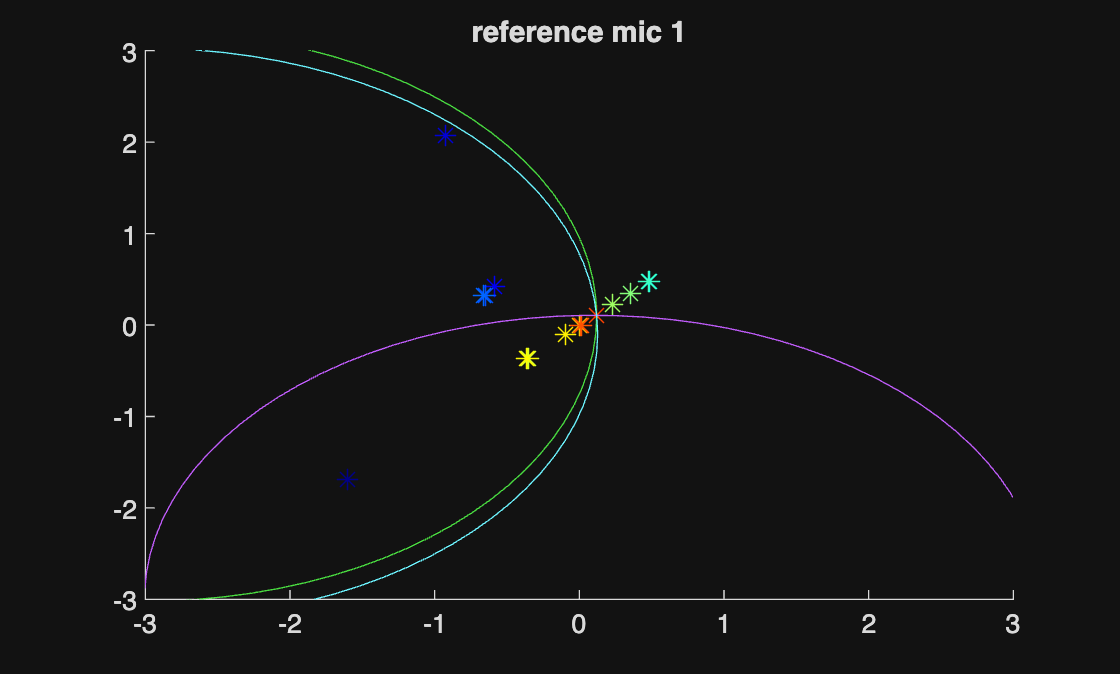

%reference mic 1

cmap = jet(length(tau_12));
figure
hold on
title('reference mic 1')
xlim([-3 3])
ylim([-3 3])

for i = 1:length(tau_12)

    vopt = solve_t_positive(tau_12(i),tau_13(i),tau_14(i),m_2,m_3,m_4);
    
    if ~isempty(vopt)
        first  = plotCircle(m_2, v * abs(tau_12(i) + vopt(3)));
        second = plotCircle(m_3, v * abs(tau_13(i) + vopt(3)));
        third  = plotCircle(m_4, v * abs(tau_14(i) + vopt(3)));
        pause(0.25 * temps_entre_position);
    
        plot(vopt(1), vopt(2), '*', 'Color', cmap(i,:), 'MarkerSize', 8);
        pause(0.15 * temps_entre_position);
    
        delete(first);
        delete(second);
        delete(third);
        pause(0.6 * temps_entre_position);
    end

end


%reference mic 2

cmap = jet(length(tau_21));
figure
hold on
title('reference mic 2')
xlim([-3 3])
ylim([-3 3])
for i = 1:length(tau_21)

    vopt = solve_t_positive(tau_21(i),tau_23(i),tau_24(i),m_1,m_3,m_4);

    if ~isempty(vopt)
        first = plotCircle(m_1, v*abs(tau_21(i)+vopt(3)));
        second = plotCircle(m_3, v*abs(tau_23(i)+vopt(3)));
        third = plotCircle(m_4, v*abs(tau_24(i)+vopt(3)));
        pause(0.25*temps_entre_position)
    
        plot(vopt(1), vopt(2), '*', 'Color', cmap(i,:), 'MarkerSize', 8);
        pause(0.15*temps_entre_position)
        delete(first)
        delete(second)
        delete(third)
        pause(0.6*temps_entre_position)
    end
end

%reference mic 3

cmap = jet(length(tau_31)+100);
figure
hold on
title('reference mic 3')
xlim([-3 3])
ylim([-3 3])
for i = 1:length(tau_31)

    vopt = solve_t_positive(tau_31(i),tau_32(i),tau_34(i),m_1,m_2,m_4);


    if ~isempty(vopt)
        first = plotCircle(m_1, v*abs(tau_31(i)+vopt(3)));
        second = plotCircle(m_2, v*abs(tau_32(i)+vopt(3)));
        third = plotCircle(m_4, v*abs(tau_34(i)+vopt(3)));
        pause(0.25*temps_entre_position)
    
        plot(vopt(1), vopt(2), '*', 'Color', cmap(i,:), 'MarkerSize', 8);
        pause(0.15*temps_entre_position)
        delete(first)
        delete(second)
        delete(third)
        pause(0.6*temps_entre_position)
    end
end


%reference mic 4

cmap = jet(length(tau_41));
figure
hold on
title('reference mic 4')
sol4=zeros(3,length(tau_41));
xlim([-3 3])
ylim([-3 3])
for i = 1:length(tau_41)

    vopt = solve_t_positive(tau_41(i),tau_42(i),tau_43(i),m_1,m_2,m_3);


    if ~isempty(vopt)
        first = plotCircle(m_1, v*abs(tau_41(i)+vopt(3)));
        second = plotCircle(m_2, v*abs(tau_42(i)+vopt(3)));
        third = plotCircle(m_3, v*abs(tau_43(i)+vopt(3)));
        pause(0.25*temps_entre_position)
    
        plot(vopt(1), vopt(2), '*', 'Color', cmap(i,:), 'MarkerSize', 8);
        pause(0.15*temps_entre_position)
        delete(first)
        delete(second)
        delete(third)
        pause(0.6*temps_entre_position)
    end
end
